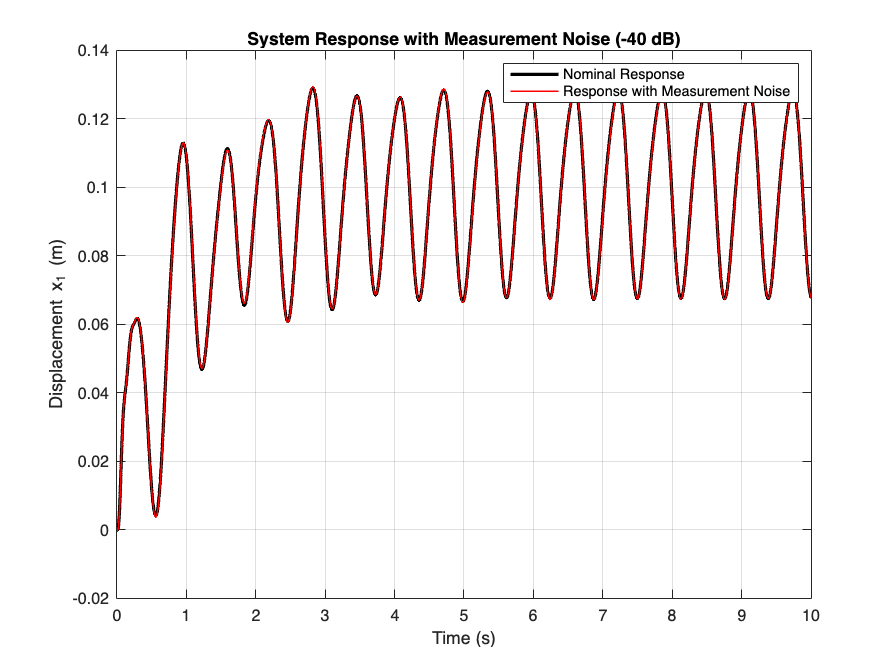

clc; clear; close all;

M = 300; m = 50; D = 1000;
k1_nom = 15000; k2_nom = 150000;

Kp = 1601; 
Ki = 20950; 
C = pid(Kp, Ki);
Kd = -15000; 
t = 0:0.001:10;
R = 0.1 * ones(size(t));
Yr = 0.1 + 0.05*sin(10*t) + 0.02*cos(20*t);

get_sys = @(k1, k2) minreal(tf(ss(...
    [0 0 1 0; 0 0 0 1; -k1/M k1/M -D/M D/M; k1/m -(k1+k2)/m D/m -D/m], ...
    [0 0; 0 0; 1/M 0; -1/m k2/m], ...
    [1 0 0 0], 0))); 

sys_nom = get_sys(k1_nom, k2_nom);
G_nom = sys_nom(:,1); 
H_nom = sys_nom(:,2); 

T_ref_nom = feedback(C * G_nom, 1);
T_dist_nom = (H_nom + G_nom * Kd) / (1 + C * G_nom);
T_noise_nom = -feedback(C * G_nom, 1); 

y_nom = lsim(T_ref_nom, R, t) + lsim(T_dist_nom, Yr, t);


noise_std = sqrt(10^(-40/10)); 
n_t = noise_std * randn(size(t)); 

y_noisy = y_nom + lsim(T_noise_nom, n_t, t);

figure('Name', 'Part 5a: Measurement Noise', 'Color', 'w');
plot(t, y_nom, 'k', 'LineWidth', 2); hold on;
plot(t, y_noisy, 'r', 'LineWidth', 1);
grid on; title('System Response with Measurement Noise (-40 dB)');
xlabel('Time (s)'); ylabel('Displacement x_1 (m)');
legend('Nominal Response', 'Response with Measurement Noise');

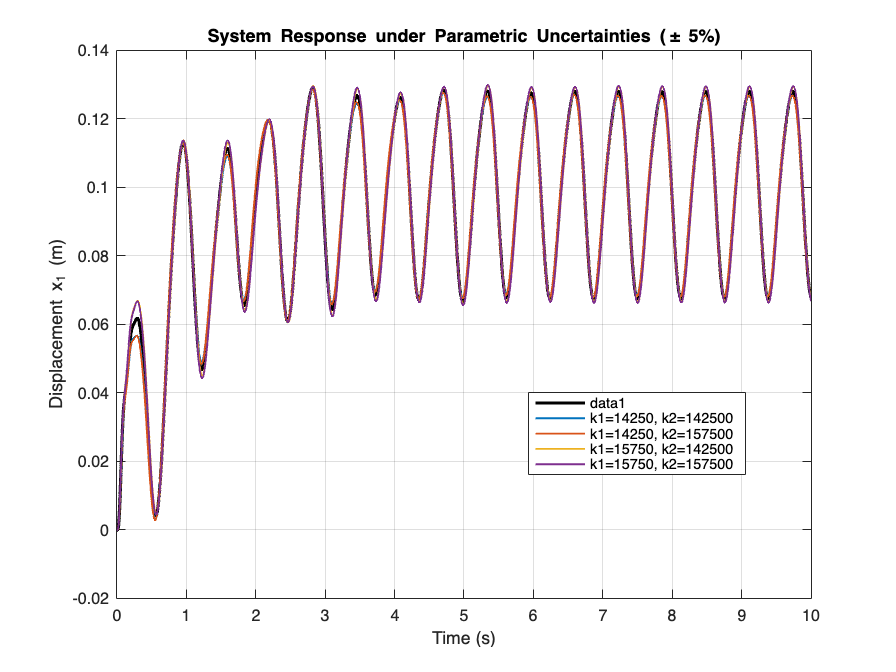


k1_vars = [k1_nom*0.95, k1_nom*1.05];
k2_vars = [k2_nom*0.95, k2_nom*1.05];

figure('Name', 'Part 5b: Parametric Uncertainty', 'Color', 'w');
plot(t, y_nom, 'k', 'LineWidth', 2); hold on;

colors = lines(4); idx = 1;
for k1_unc = k1_vars
    for k2_unc = k2_vars
        sys_unc = get_sys(k1_unc, k2_unc);
        G_unc = sys_unc(:,1); H_unc = sys_unc(:,2);
        
        T_ref_unc = feedback(C * G_unc, 1);
        T_dist_unc = (H_unc + G_unc * Kd) / (1 + C * G_unc);
        
        y_unc = lsim(T_ref_unc, R, t) + lsim(T_dist_unc, Yr, t);
        plot(t, y_unc, 'Color', colors(idx,:), 'LineWidth', 1.2, ...
             'DisplayName', sprintf('k1=%.0f, k2=%.0f', k1_unc, k2_unc));
        idx = idx + 1;
    end
end
grid on; title('System Response under Parametric Uncertainties (\pm 5%)');
xlabel('Time (s)'); ylabel('Displacement x_1 (m)');
legend('Location', 'best');

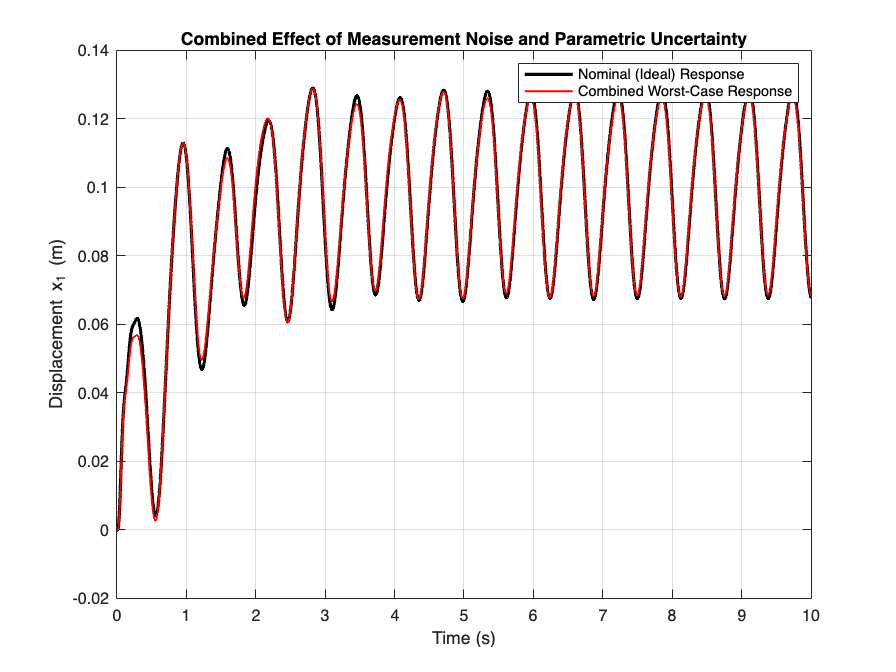


sys_worst = get_sys(k1_vars(1), k2_vars(1)); 
G_worst = sys_worst(:,1); H_worst = sys_worst(:,2);

T_ref_worst = feedback(C * G_worst, 1);
T_dist_worst = (H_worst + G_worst * Kd) / (1 + C * G_worst);
T_noise_worst = -feedback(C * G_worst, 1);

y_combined = lsim(T_ref_worst, R, t) + lsim(T_dist_worst, Yr, t) + lsim(T_noise_worst, n_t, t); 

figure('Name', 'Part 5c: Combined Robustness', 'Color', 'w');
plot(t, y_nom, 'k', 'LineWidth', 2); hold on;
plot(t, y_combined, 'r', 'LineWidth', 1.2);
grid on; title('Combined Effect of Measurement Noise and Parametric Uncertainty');
xlabel('Time (s)'); ylabel('Displacement x_1 (m)');
legend('Nominal (Ideal) Response', 'Combined Worst-Case Response');